# Digital Image processing

### For simple digital image processing we use some basic functions of MATLAB. A brief explanation of each needed function is provided.

**imread()** Read image from graphics file. A = imread(FILENAME,FMT) reads a grayscale or color image from the file specified by the character vector or string scalar FILENAME. FILENAME must be in the current directory, in a directory on the MATLAB path, or include a full or relative path to a file.

**imhist() **Display histogram of N-D image data. imhist(I) displays a histogram for the intensity image I whose number of bins are specified by the image type.  If I is a grayscale image, imhist uses 256 bins as a default value. If I is a binary image, imhist uses only 2 bins. I can be 2-D, 3-D or N-D.

**histeq()** Enhance contrast using histogram equalization. It enhances the contrast of images by transforming the values in anintensity image, or the values in the colormap of an indexed image, so that the histogram of the output image approximately matches a specified histogram.

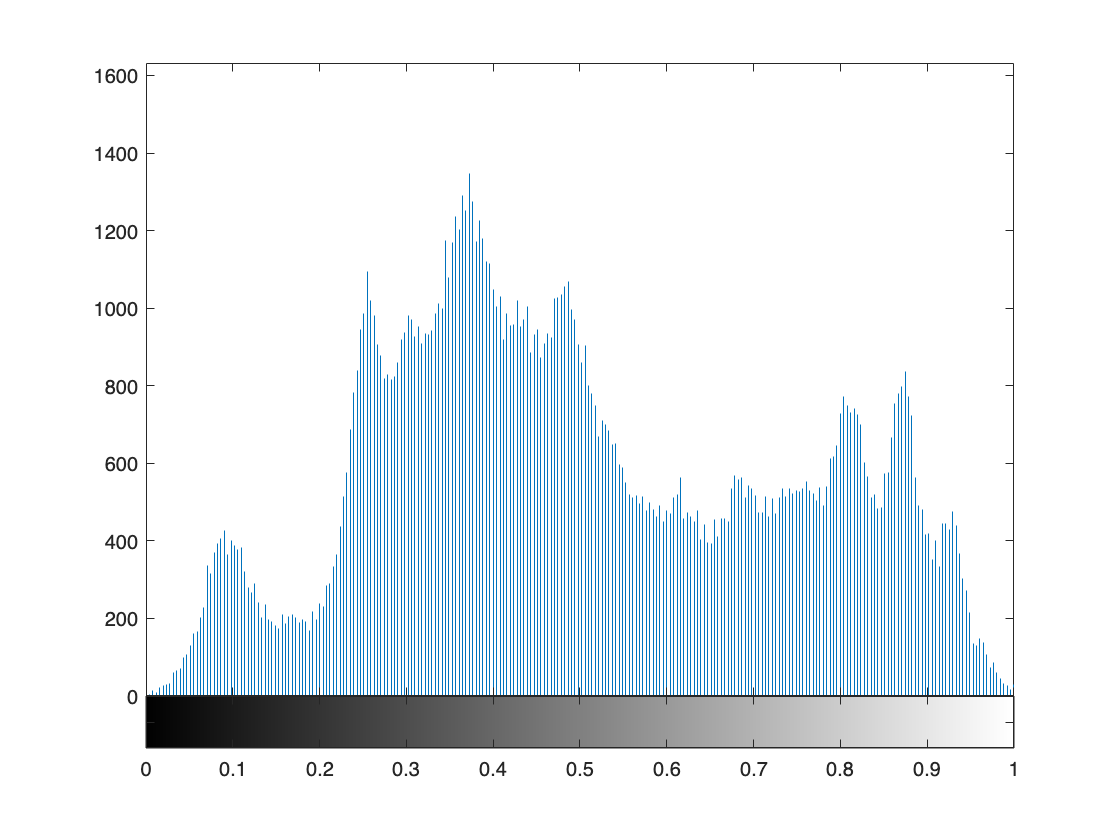

x=imread("lena.png");
x_d=im2double(x);
figure()
imhist(x_d);

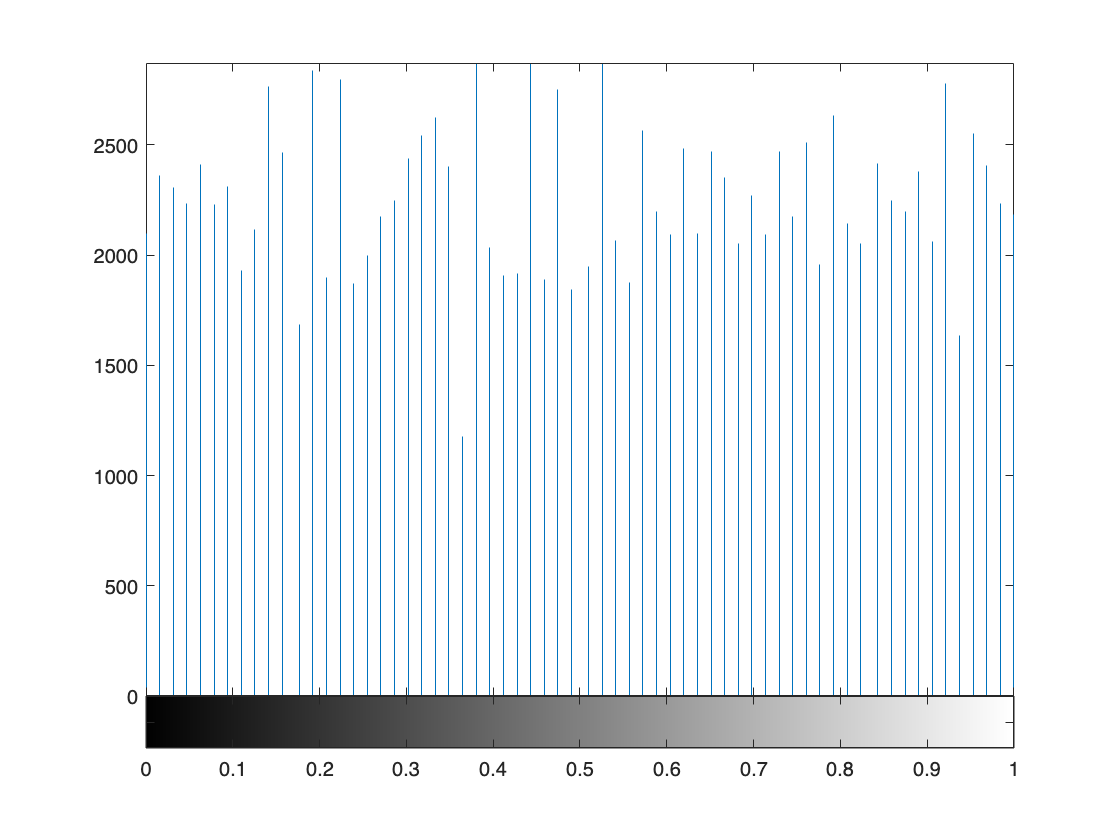

x_d_eq=histeq(x_d);
figure()
imhist(x_d_eq);

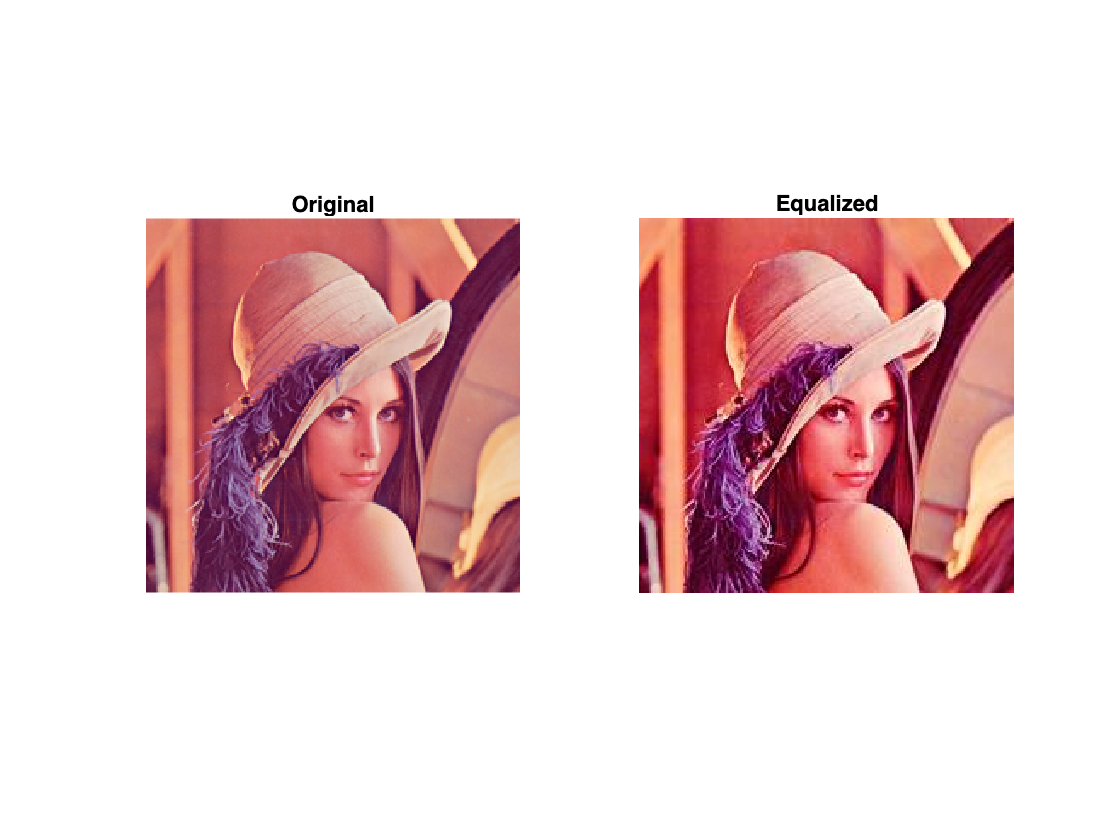


imwrite(x_d_eq,"Equalized lena.png");
figure()
subplot(1,2,1)
imshow("lena.png");
title("Original")
subplot(1,2,2)
imshow("Equalized lena.jpg");
title("Equalized")

If we look at the histogram of equalized image using histeq() function, It's obvious that the ploted histogram is not actually uniform. three possible reasons are:

- Limited Intensity Range: The intensity range of the original image may be limited, meaning that there might be a concentration of pixel intensities in a narrow range. Histogram equalization redistributes these intensities, but it is constrained by the available range, which can limit the ability to achieve a perfectly uniform histogram.

- Nonlinear Mapping: The mapping function used in histogram equalization is nonlinear. It stretches or compresses the intensity values to achieve a more balanced distribution. This nonlinear mapping can introduce deviations from a perfectly uniform histogram.

- Discrete Nature of Pixel Intensities: Digital images have a finite number of discrete intensity levels. The quantization effect of these discrete levels can further limit the ability to achieve a perfectly uniform histogram.

# Image denoising

### First we add a gaussian noise with u=0 , std=0.2 parameters

**imnoise() **function is used to add noise to an image. We can simply add a gaussian noise with specific parameters with this format                                                        noisy_image=imnoise(image , 'gaussian' , mean , std)

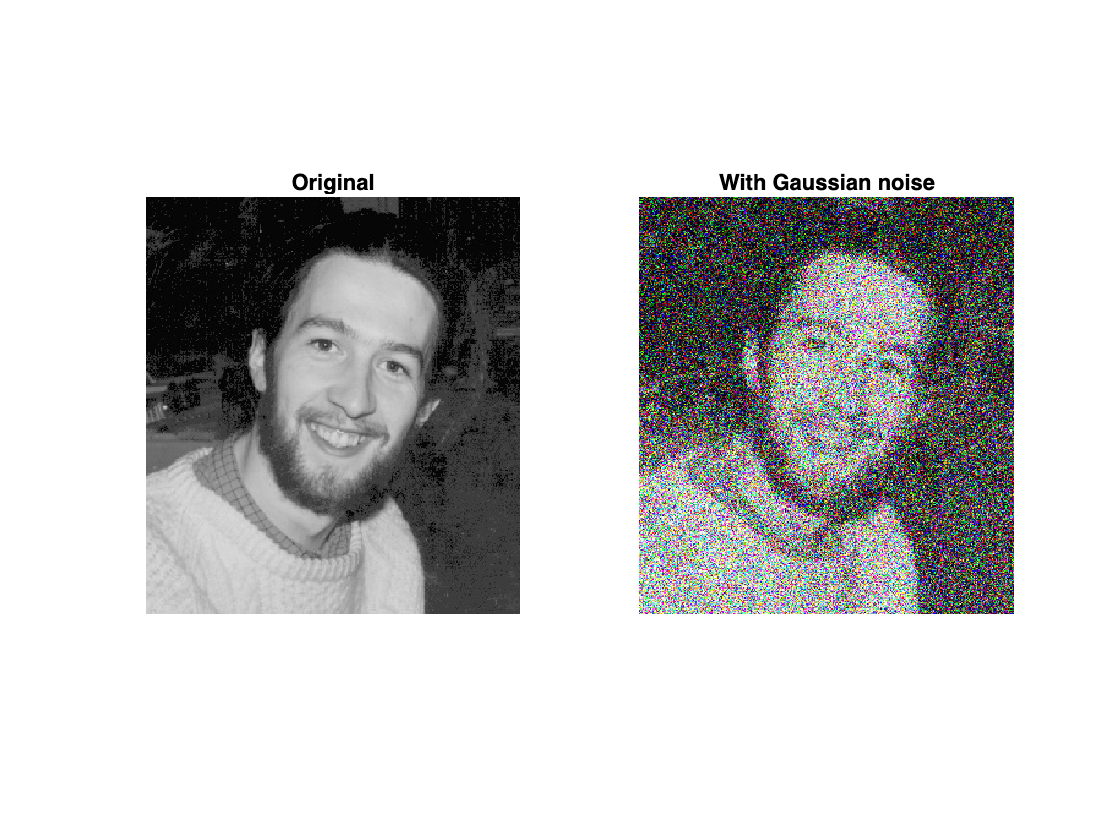

image02=imread("Image02.jpg");
noisy_image02=imnoise(image02,'gaussian',0,0.2);
figure();
subplot(1,2,1)
imshow(image02)
title("Original")
subplot(1,2,2)
imshow(noisy_image02)
title("With Gaussian noise");

# Denoising using 3x3 mean filter method

### First we define a 3x3 mean filter to use mean filtering method.

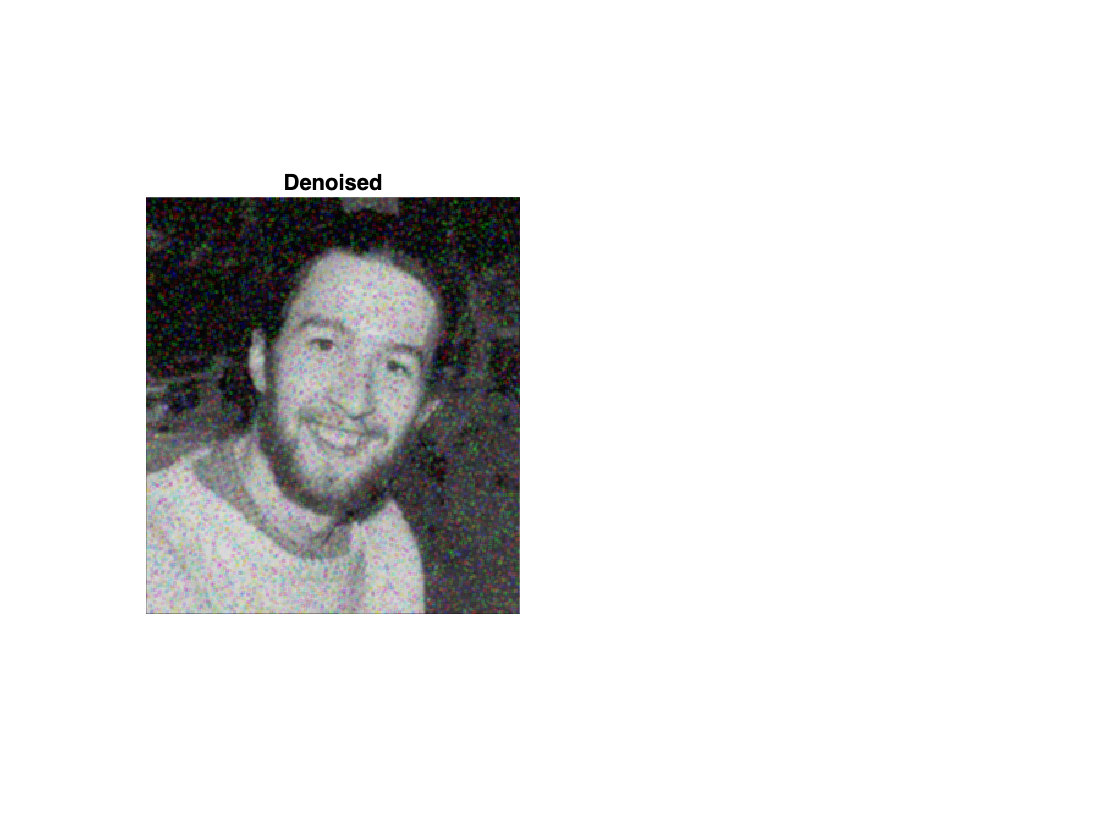

a=1/9;
mean_filter=[a,a,a;a,a,a;a,a,a];
denoised1=imfilter(noisy_image02,mean_filter,'conv','circular');
figure();
subplot(1,2,1)
imshow(denoised1)
title("Denoised by 3x3 mean filter")

The result image after filtering with 3x3 mean fiter shows that this method worked! But noise pixels are still visible in the image.

- It's obvious that afetr filtering with the provided method, deviation of pixels has considerably decreased, so we can say, standard deviation of Gaussion noise in the filtered image has been decreased.

# Denoising using 5x5 mean filter method

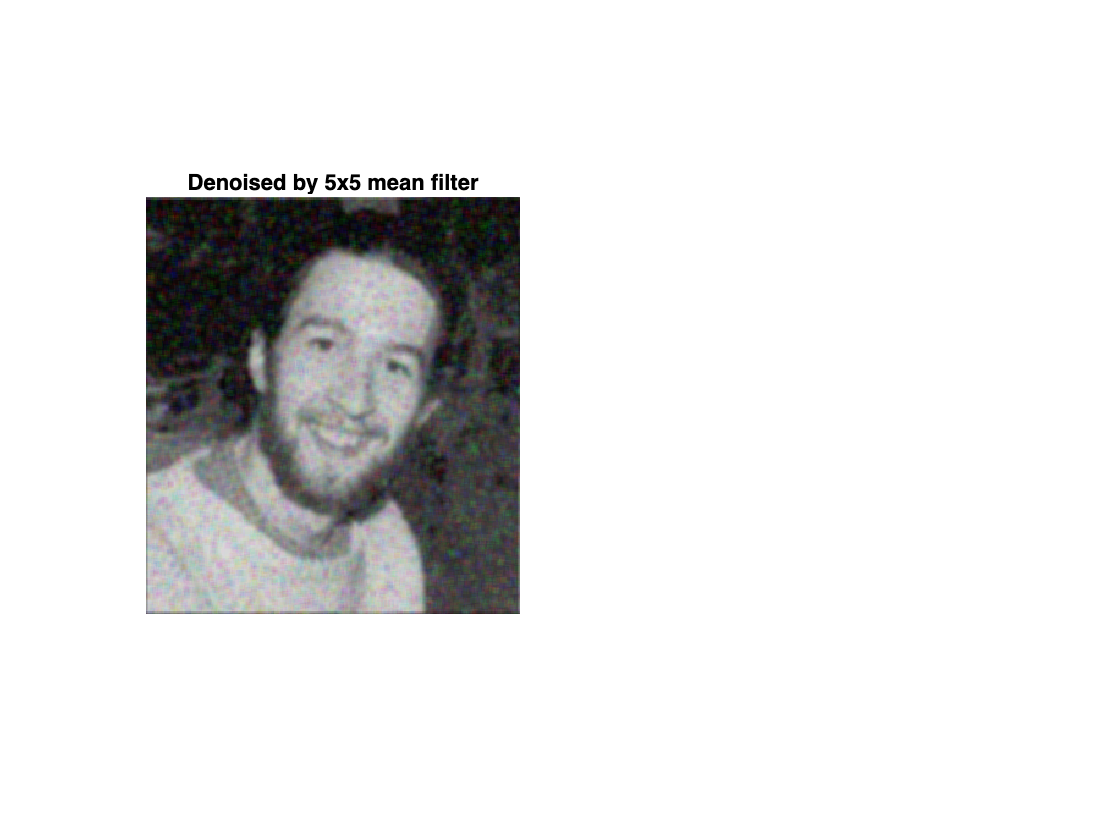

a=1/25;
mean2=[];
for k=1:5
   for i=1:5
       mean2(k,i)=a;
   end
end

denoised2=imfilter(noisy_image02,mean2,'conv','circular');
figure()
subplot(1,2,1)
imshow(denoised2)
title("Denoised by 5x5 mean filter");

The result image after filtering with 5x5 mean fiter is not as pure as the image filtered by 3x3 mean filter. It seems there is a trade-of. Gaussian noise standard deviation parameter is incredibly lower in 5x5 than that of 3x3 but more detail are visible in 3x3 mean filtered image comparing to original image.

# Salt and pepper noise

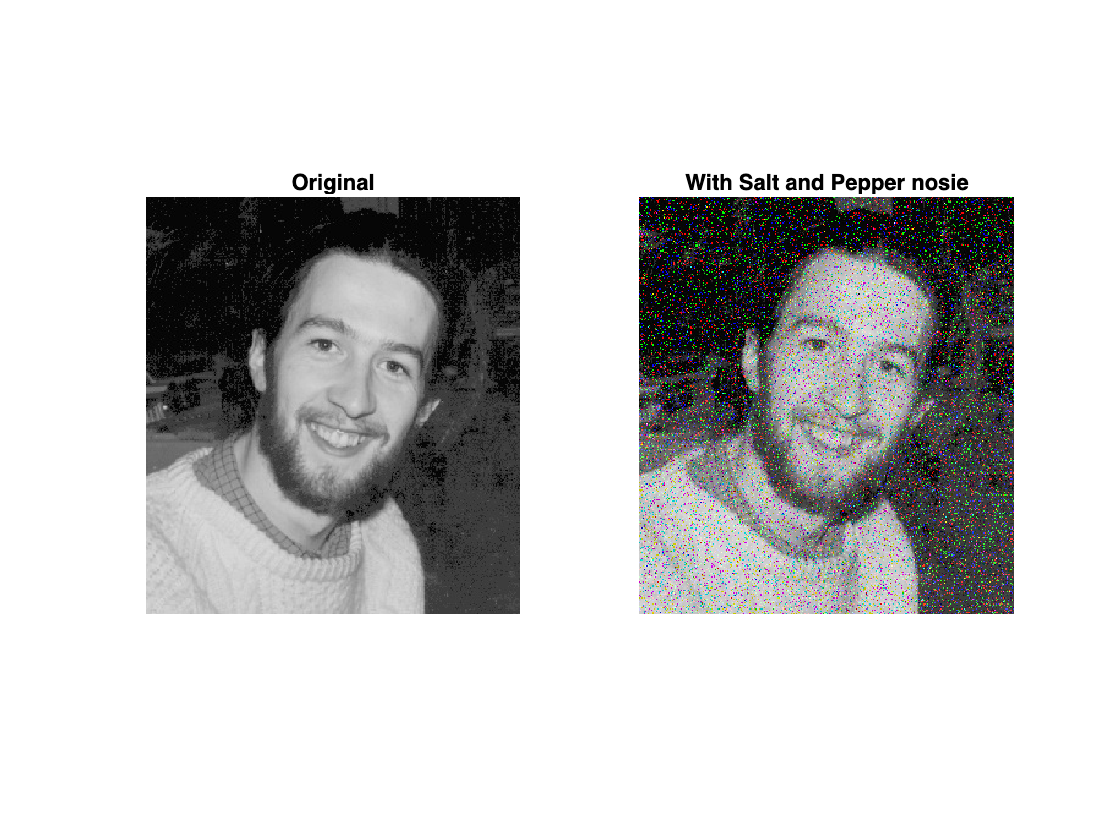

image02=imread("Image02.jpg");
noisy_image02=imnoise(image02,'salt & pepper',0.1);
figure();
subplot(1,2,1)
imshow(image02)
title("Original")
subplot(1,2,2)
imshow(noisy_image02);
title("With Salt and Pepper nosie")

Now we denoise this image using 3x3 mean filter.

denoised3=imfilter(noisy_image02,mean_filter,'conv','circular');
figure();
subplot(1,2,1)
imshow(denoised3);
title("Denoised by 3x3 mean filter");

As we see, 3x3 mean filter worked well in lowering Salt and pepper noise. 

- The effectiveness of a mean filter for salt and pepper noise reduction is due to its ability to smooth out sudden intensity variations caused by the noisy pixels. However, it's worth noting that a mean filter can also introduce blurring and loss of fine details in the image, especially if the noise is severe.

# FIR filter design

We want to design a low pass FIR filter with normilized pass frequency of 0.5 using filterDesigner in MATLAB.

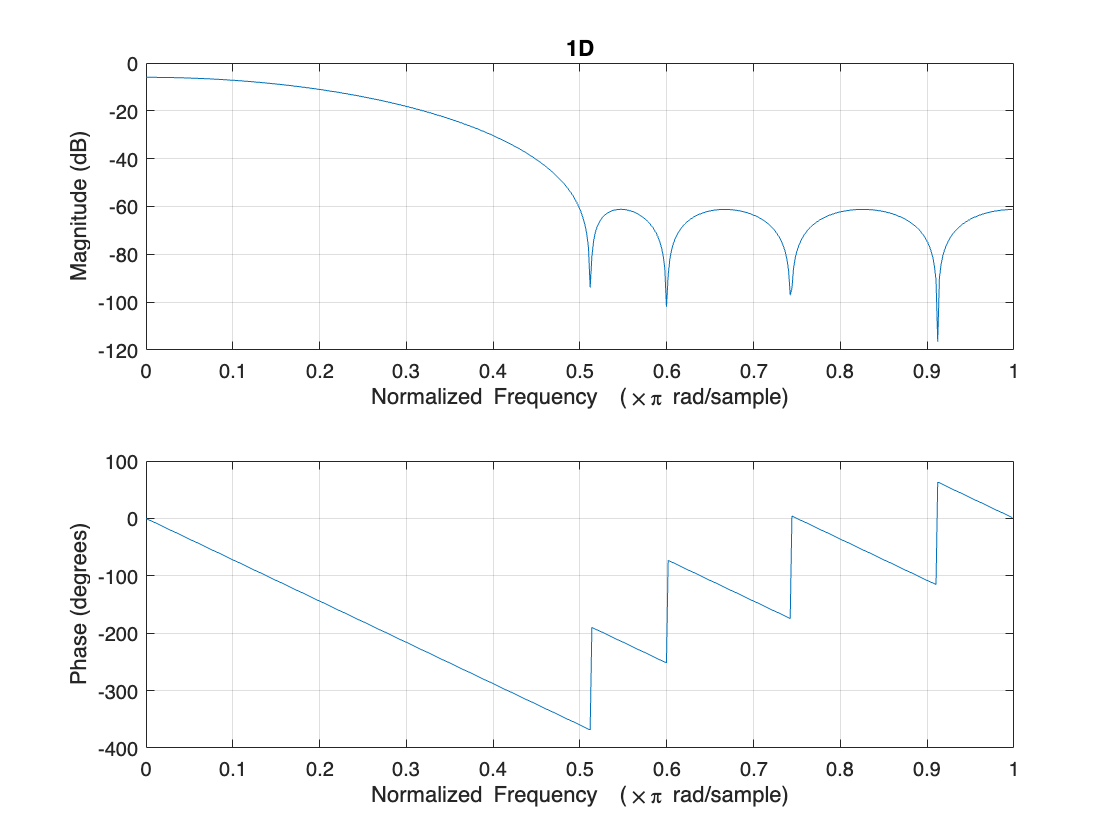

FIR=Num;
FIR_2D=ftrans2(FIR);
subplot(1,2,1)
freqz(FIR,[1]);
title("1D");

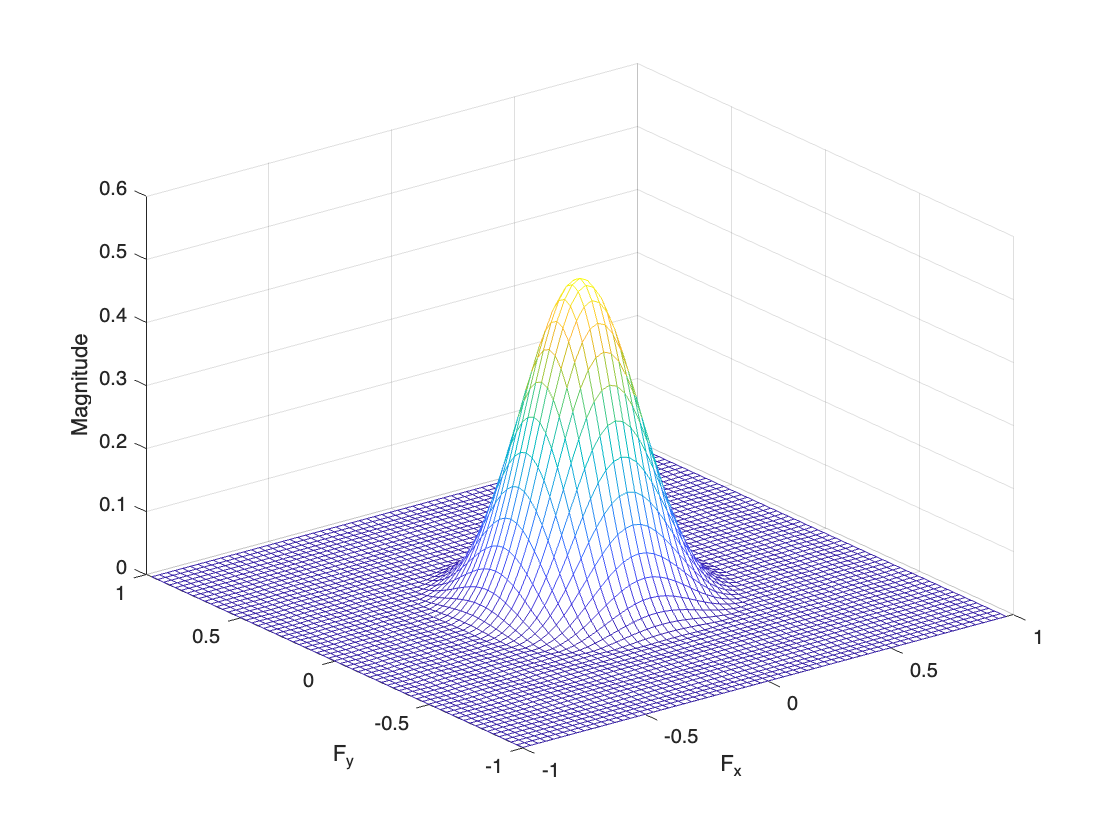

freqz2(FIR_2D);

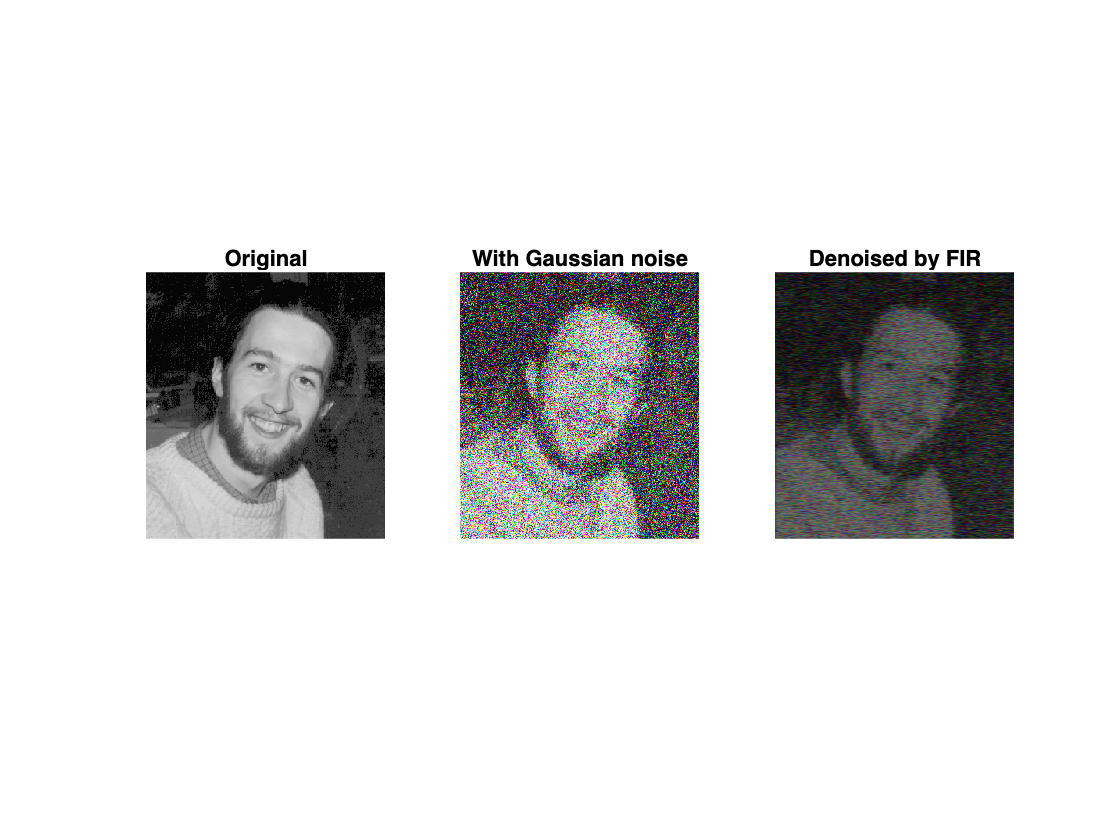

Gaussian_noise=imnoise(image02,'gaussian',0,0.2);
denoised4=imfilter(Gaussian_noise,FIR,'conv','circular');
figure()
subplot(1,3,1)
imshow(image02)
title('Original')
subplot(1,3,2)
imshow(Gaussian_noise);
title("With Gaussian noise");
subplot(1,3,3);
imshow(denoised4);
title("Denoised by FIR");

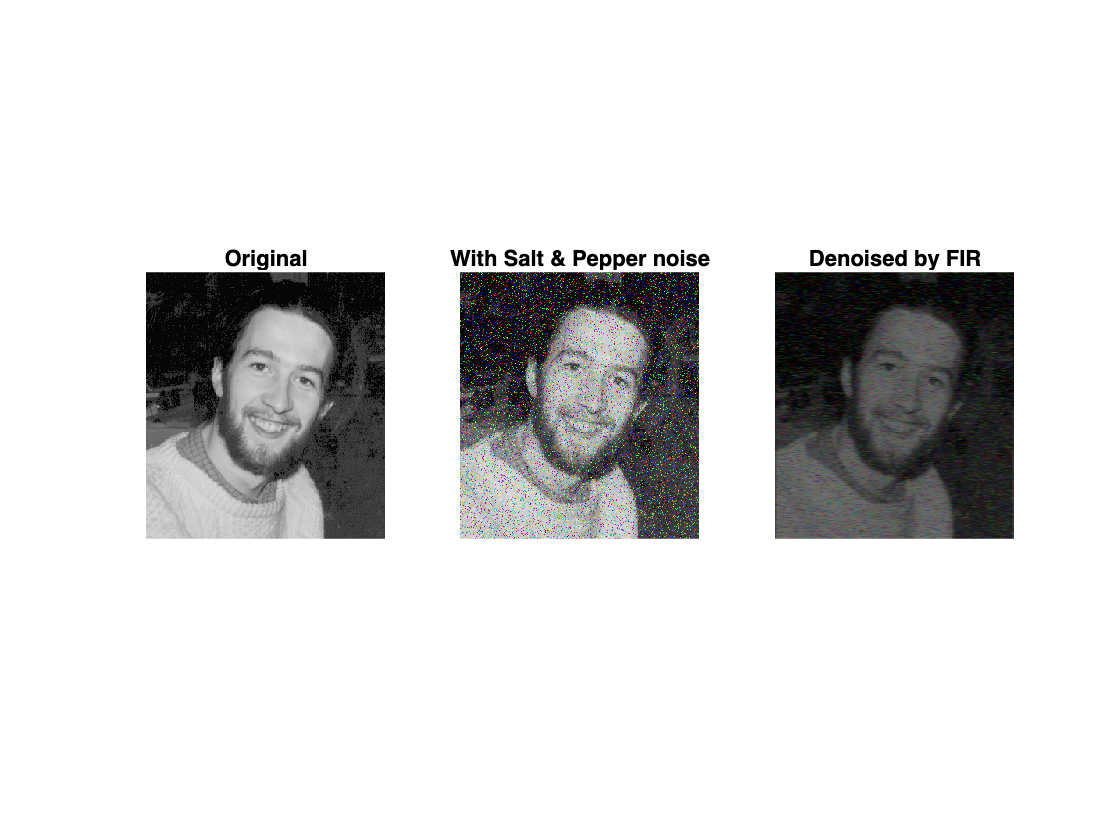

Salt_noise=imnoise(image02,'salt & pepper',0.1);
denoised5=imfilter(Salt_noise,FIR,'conv','circular');
figure()
subplot(1,3,1)
imshow(image02)
title('Original')
subplot(1,3,2)
imshow(Salt_noise);
title("With Salt & Pepper noise");
subplot(1,3,3);
imshow(denoised5);
title("Denoised by FIR");

The obvious difference between images filtered by a mean filter and FIR filter is that the image which is filtered by FIR filter has considerable lower birightness. One reason could be the coefficients of desigend filter.

# Denoising with median filter method

A median filter is a type of non-linear filter commonly used for denoising images. It works by replacing each pixel in the image with the median value of its neighborhood. There is a buit-in function for this purpose but our intention is to define the function of this filter.

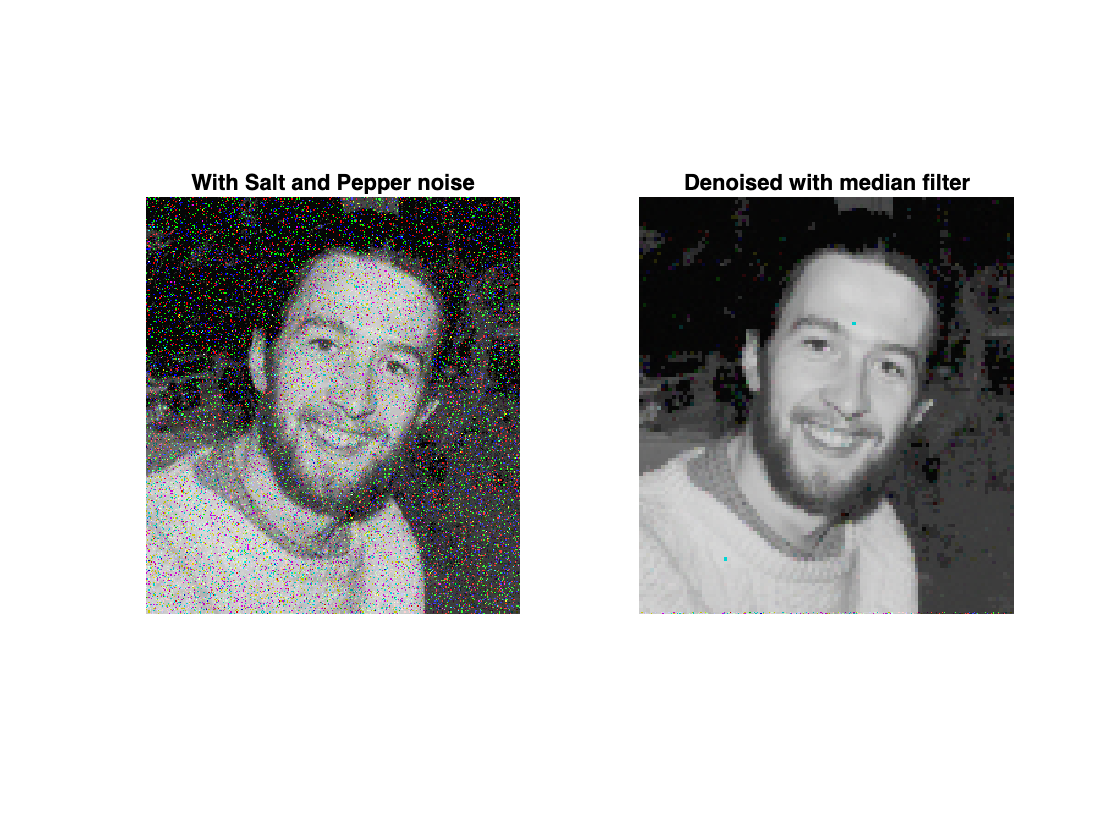

figure()
subplot(1,2,1)
imshow(Salt_noise)
title('With Salt and Pepper noise')
subplot(1,2,2);
imshow(medfilter(Salt_noise,3,3));
title("Denoised with median filter")

And we try designed Median Function for original image added Gaussian noise...

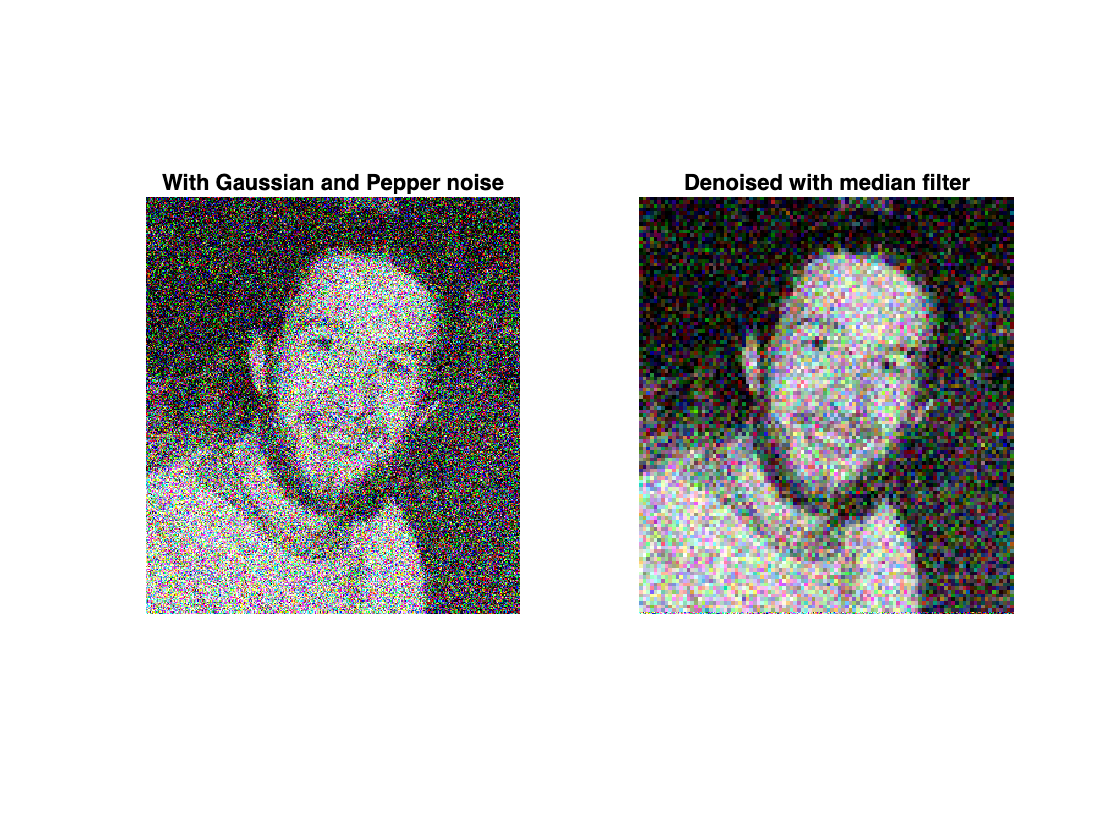

figure()
subplot(1,2,1)
imshow(Gaussian_noise)
title('With Gaussian and Pepper noise')
subplot(1,2,2);
imshow(medfilter(Gaussian_noise,3,3)); %%Median with size 3x3
title("Denoised with median filter")

- It's obvious that this filter works well to denoise images with additive Salt and Pepper noise.

- Output of Median filter for image with additive Gaussian noise in not reasonably clear so we reach a conclusion that median filter is not appropriate for denoising images with Gaussion noise added.

function filtered = medfilter(image, weight, height)
   image=im2double(image);
   if mod(weight,2) == 0 || mod(height,2) == 0 % Checking odd values for size
      warning('Please set odd values for weight and height (2nd and 3rd arguments respectively)');
   else
       [scale_x, scale_y, ~] = size(image);
       numbox_x = floor(scale_x / weight);
       numbox_y = floor(scale_y / height);

      for p = 1:3
        for k = 0:numbox_x-1
           for i = 0:numbox_y-1
                box = image((k*weight) + 1 : (k+1)*weight , (i*height) + 1 : (i+1)*height , p);
                medd = median(box(:));
                new_box = ones(weight, height, 1) * medd;
                image((k*weight) + 1 : (k+1)*weight , (i*height) + 1 : (i+1)*height , p) = new_box;
           end
        end
      end
   end
   filtered=image;
 end

 